c = 3 * 10^8;

x1 = 5000;
y1 = 6000;
x2 = 1000;
y2 = 1000;
x3 = 9000;
y3 = 1000;

dt12 = 1.47 *10^-6;
dt13 = -13.4 *10^-6;

% Из задержки вычисляем разность рассояний от ИРИ до постов
dl12 = dt12 * c;
dl13 = dt13 * c;

% Решаем систему уравнений относительно координат ИРИ
syms x y;
[x,y] = solve( ...
    sqrt((x-x1)^2 + (y-y1)^2) - sqrt((x-x2)^2 + (y-y2)^2) == dl12,  ...
    sqrt((x-x1)^2 + (y-y1)^2) - sqrt((x-x3)^2 + (y-y3)^2) == dl13, ...
    [x, y]);

% Полученные координаты
double(x)

ans = 1.9897e+03

double(y)

ans = 4.0094e+03

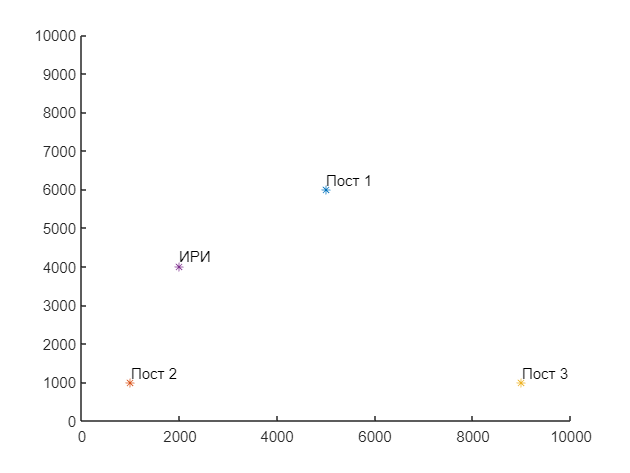


%double(sqrt((x(1)-x1)^2 + (y(1)-y1)^2)- sqrt((x(1)-x2)^2 + (y(1)-y2)^2))
%double(sqrt((x-x1)^2 + (y-y1)^2) - sqrt((x-x3)^2 + (y-y3)^2))

%Сторим графики
clf reset
hold on
plot(x1, y1, 'Marker', '*')
text(x1, y1+250, "Пост 1")
plot(x2, y2, 'Marker', '*')
text(x2, y2+250, "Пост 2")
plot(x3, y3, 'Marker', '*')
text(x3, y3+250, "Пост 3")
plot(x,y, 'Marker', '*')
text(x, y+250, "ИРИ")
xlim([0, 10000])
ylim([0, 10000])
hold off